# Event distance analysis (tube events)

### 1 Simplify events by removing M duplicates and selecting specified K 

If multiple events are significant starting at the same time for the same length, only keep the one with highest number of neurons 

% get simplified events and antievents
load('em_18p_th0.5.mat')
load('dTT_SYN_18Pair_R3_10032020.mat')
em=rem_dup_em(em);
[N,nm]=size(em{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
% events
for r=1:2 % two rounds 
    allt=cell(N,nm);allm=cell(N,nm);allk=cell(N,nm);
    for p=1:N
        for m=1:nm
            [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
        end
    end
    em{r,1}.allt=allt;em{r,1}.allm=allm;em{r,1}.klist=klist;em{r,1}.allk=allk;
end

### Plot events

After selecting events of the 4 lengths, plot each event as one line. Interacting mice are plotted together with correlaponding rasters.

Orange = subordinate animal events; Blue = dominant animal events

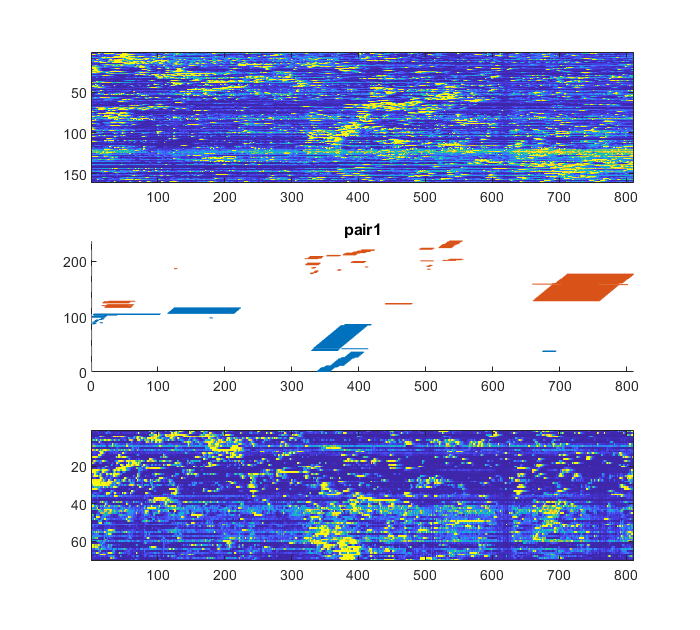

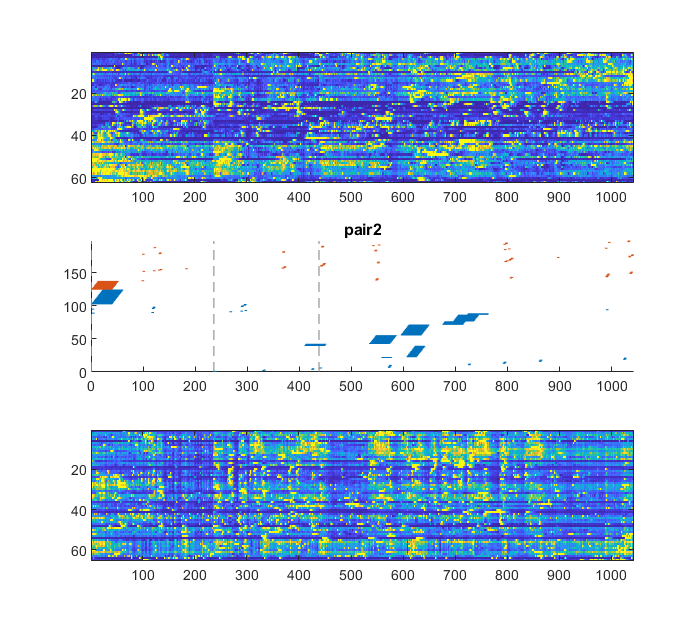

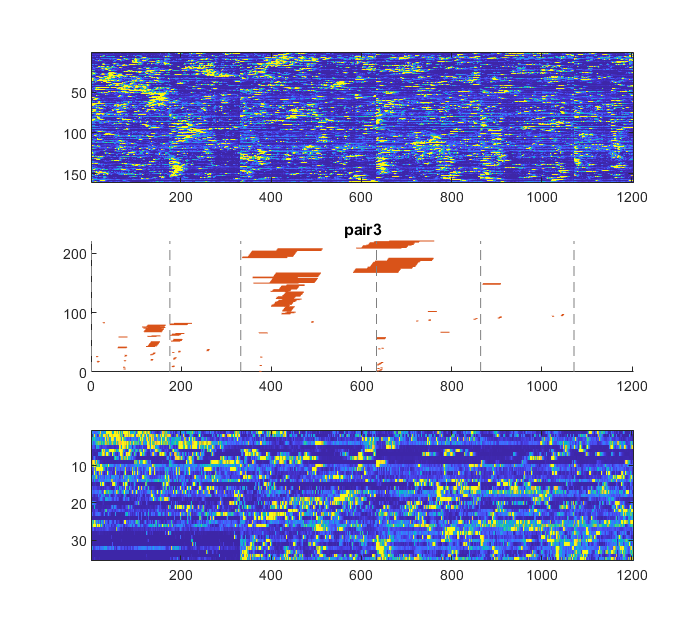

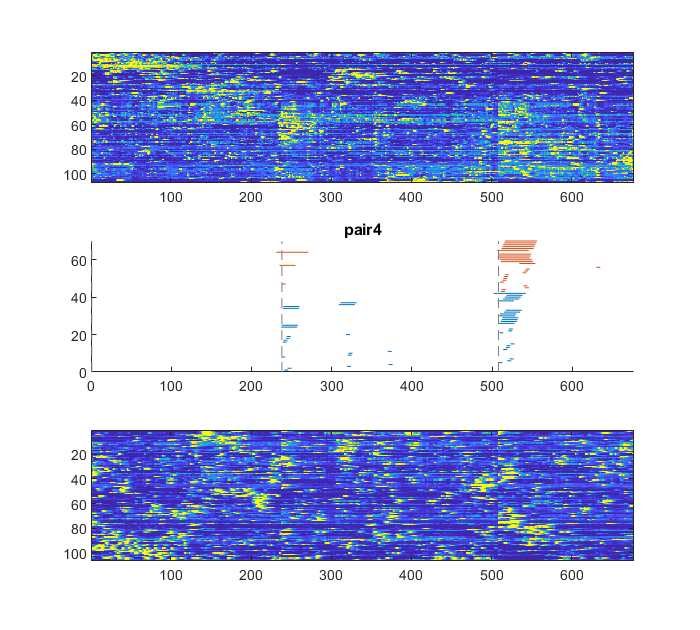

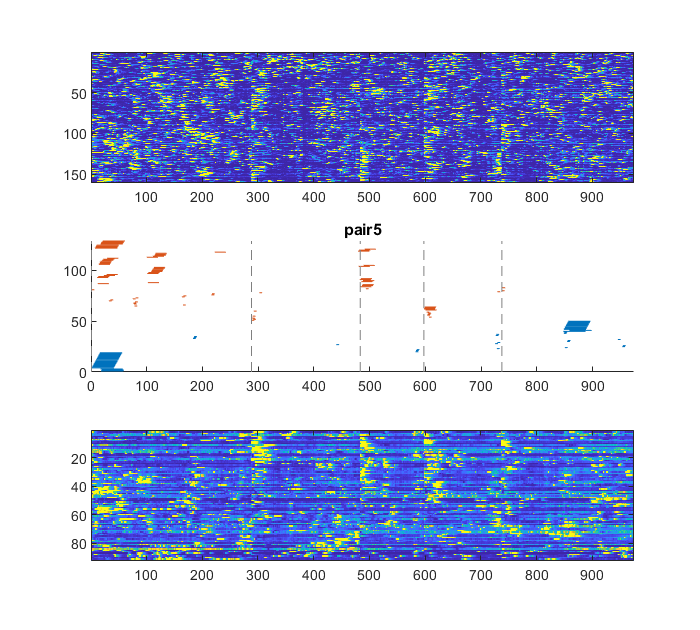

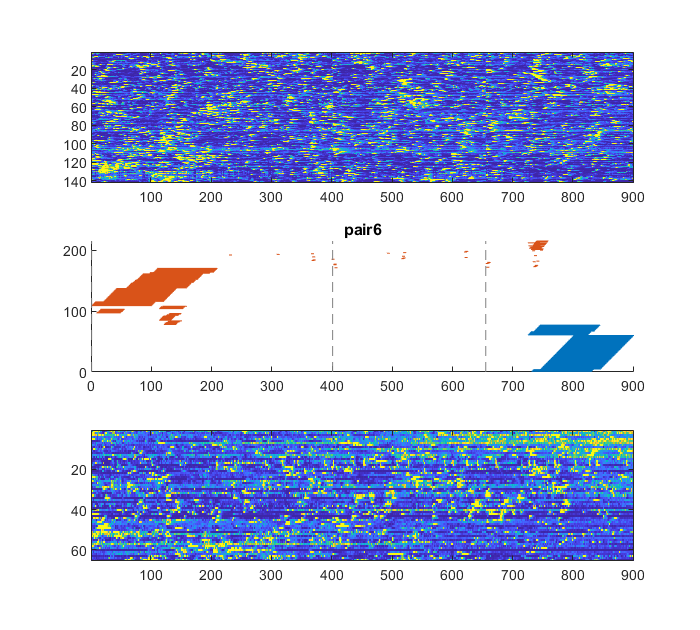

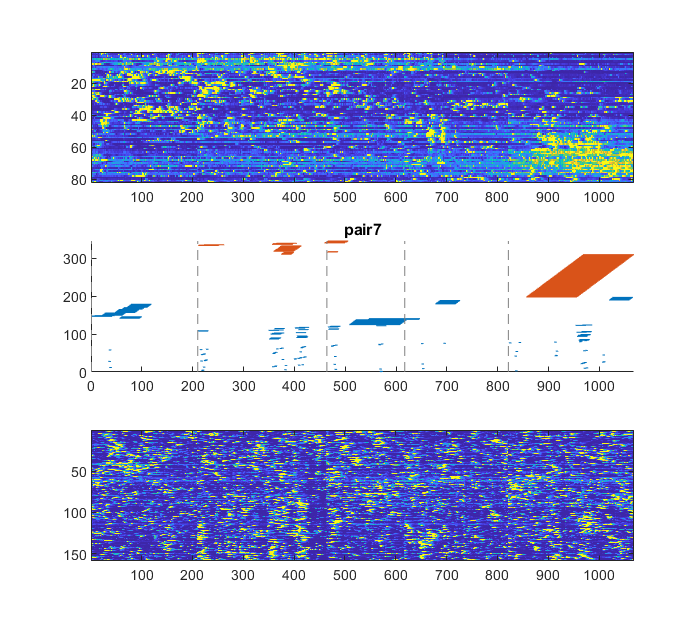

close all
for p=1:N
    f=figure;f.Position(4)=1.2*f.Position(4);
    subplot(3,1,2)
    totalt=size(em{1,1}.ca_cl{p,1},2);
    et11=em{1,1}.allt{p,1};et12=em{2,1}.allt{p,1};
    et21=em{1,1}.allt{p,2};et22=em{2,1}.allt{p,2};
    maxy=eventplot_lines(et11,em{1,1}.allk{p,1},1:totalt);
    hold on
    maxy=eventplot_lines(et12,em{2,1}.allk{p,1},find(em{2,1}.timefilter{p,1}),"y0",maxy);
    maxy=eventplot_lines(et21,em{1,1}.allk{p,2},1:totalt,'y0',maxy,"col",[0.8500 0.3250 0.0980]);
    maxy=eventplot_lines(et22,em{2,1}.allk{p,2},find(em{2,1}.timefilter{p,2}),'y0',maxy,"col",[0.8500 0.3250 0.0980]);
    onset = sum(reshape(E{p}{1}.BehaviorVectors(1:30*totalt,4),30,totalt),1); % mark event onset 
    plot(repmat(find(onset),2,1),repmat([0;maxy],1,length(find(onset))),'--','Color',0.5*[1,1,1])
    hold off
    xlim([0 totalt]);ylim([0 maxy])
    title(sprintf('pair%d',p))
%     % NOTE - run this title only after synchronization percentage is derived !!
%       % here plotting K=5,20,40,100
%       for k=1:4
%         perc(k,:)=[synwithin(k,1:2),0,synwithin(k,3:end)]; % resume third pair to be 0
%       end
%     title(sprintf('pair%d,%%syn5s=%.2g,%%syn20s=%.2g,%%syn40s=%.2g,%%syn100s=%.2g',p,perc(1,p),perc(2,p),perc(3,p),perc(4,p)))
%     % -------
    subplot(3,1,3)
    S0=em{1,1}.ca_cl{p,1};
    ops.iPC=1:35;
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
    subplot(3,1,1)
    S0=em{1,1}.ca_cl{p,2};
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
end

Remove pair 3 for lack of events 

for r=1:2
em{r,1}.allk=em{r,1}.allk([1,2,4:end],:);em{r,1}.allm=em{r,1}.allm([1,2,4:end],:);em{r,1}.allt=em{r,1}.allt([1,2,4:end],:);
end
N=N-1;

### Calculate distance between events for each k 

For each event in one animal, calculate the distance between the center of this event and the nearest event in the other animal. 

ev_merge=cell(N,nm); % center of all events 
for p=1:N
    for m=1:nm
        ev_merge{p,m}=cell(1,4);
        for k=1:4
            % merge events from the two rounds of detection 
            ev_merge{p,m}{k}=em{1,1}.allt{p,m}{k}+klist{k}/2;
            ev_merge{p,m}{k}=[ev_merge{p,m}{k},em{2,1}.allt{p,m}{k}+klist{k}/2];
        end
    end
end
% within-pair distance 
distwithin=cell(1,4);distbetween=cell(1,4);
for p=1:N
    for m=1:2
        for k=1:4
        distwithin{k}(p,m)=mean(eventdist(ev_merge{p,m}{k},ev_merge{p,setdiff([1 2],m)}{k}));
        end
    end 
end
perm=cell(1,100); % random 100 between-pair permutations 
for r = 1:100
    perm{r}=randperm(N*2);
    perm{r}=reshape(perm{r},N,2);
    while any(perm{r}(:,1)-perm{r}(:,2)==1) % make sure no same pair come together
        perm{r}=randperm(N*2);
        perm{r}=reshape(perm{r},N,2);
    end 
    for p=1:N
        for k=1:4
            [p1,m1]=ind2sub([N,2],perm{r}(p,1));[p2,m2]=ind2sub([N,2],perm{r}(p,2));
            distbetween{k}(r,p)=mean(eventdist(ev_merge{p1,m1}{k},ev_merge{p2,m2}{k}));
        end
    end 
end
for k =1:4
rs(k)=ranksum(distwithin{k}(:),distbetween{k}(:));
end

### Plot distance 

a. within pair - between pair, the mean distance for each animal is plotted as one dot. 

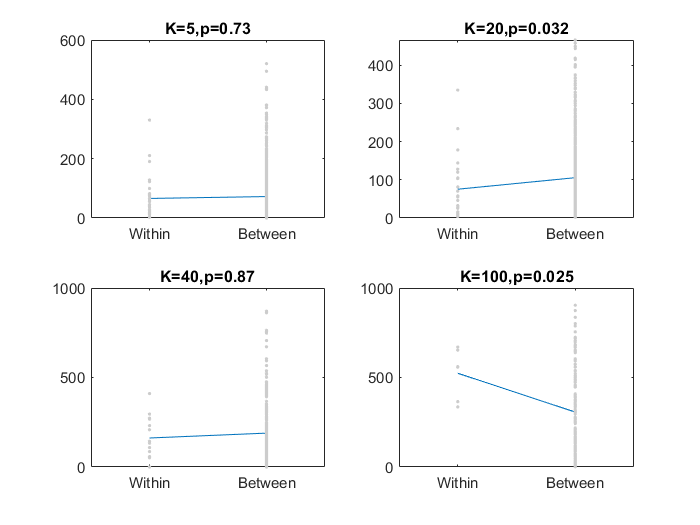

close all
for k=1:4
    subplot(2,2,k)
    plot([nanmean(distwithin{k},'all'),nanmean(distbetween{k},'all')],'-');hold on
    plot(ones(1,2*N),distwithin{k}(:),'.',"Color",0.8*[1,1,1]);
    plot(repelem(2,1,N*100),distbetween{k}(:),'.',"Color",0.8*[1,1,1]);
    xlim([0.5 2.5]);xticks([1 2]);
    xticklabels({'Within','Between'});
    title(sprintf('K=%d,p=%.2g',klist{k},rs(k)))
end

### Calculate distance for all Ks taken together 

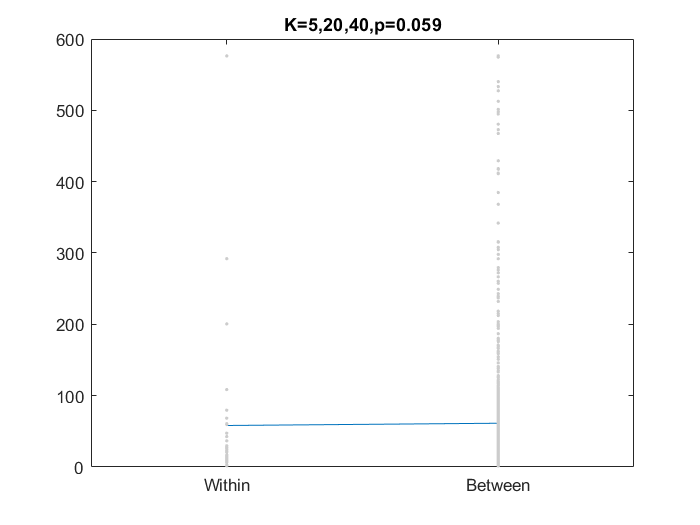

close all 
kind=[1,2,3];distwithin=[];distbetween=[];
ev_merge=cell(N,nm); % center of all events 
for p=1:N
    for m=1:nm
        for k=1:4
            % merge events from the two rounds of detection 
            ev_merge{p,m}=[ev_merge{p,m},em{1,1}.allt{p,m}{k}+klist{k}/2];
            ev_merge{p,m}=[ev_merge{p,m},em{2,1}.allt{p,m}{k}+klist{k}/2];
        end
    end
end
% within-pair distance 
for p=1:N
    for m=1:2
        distwithin(p,m)=mean(eventdist(ev_merge{p,m},ev_merge{p,setdiff([1 2],m)}));
    end 
end
perm=cell(1,100); % random 100 between-pair permutations 
for r = 1:100
    perm{r}=randperm(N*2);
    perm{r}=reshape(perm{r},N,2);
    while any(perm{r}(:,1)-perm{r}(:,2)==1) % make sure no same pair come together
        perm{r}=randperm(N*2);
        perm{r}=reshape(perm{r},N,2);
    end 
    for p=1:N
            [p1,m1]=ind2sub([N,2],perm{r}(p,1));[p2,m2]=ind2sub([N,2],perm{r}(p,2));
            distbetween(r,p)=mean(eventdist(ev_merge{p1,m1},ev_merge{p2,m2}));
    end 
end
rs=ranksum(distwithin(:),distbetween(:));
plot([nanmean(distwithin,'all'),nanmean(distbetween,'all')],'-');hold on
    plot(ones(1,2*N),distwithin(:),'.',"Color",0.8*[1,1,1]);
    plot(repelem(2,1,N*100),distbetween(:),'.',"Color",0.8*[1,1,1]);
    xlim([0.5 2.5]);xticks([1 2]);
    xticklabels({'Within','Between'});
    title(sprintf('K=5,20,40,p=%.2g',rs))

b. comparison between dominant and subordinate animals 

Compare dominant to subordinate distance and subordinate to dominant distance to assess relative synchrony within pairs

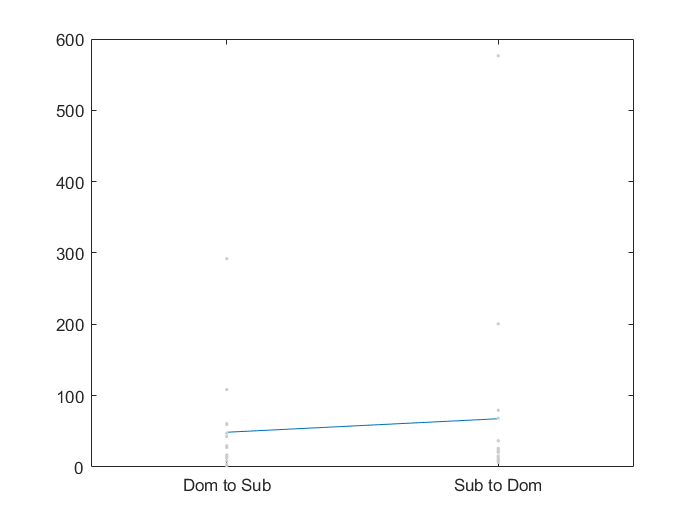

close all
plot(mean(distwithin),'-');hold on
plot(repmat([1 2],N,1),distwithin,'.',"Color",0.8*[1,1,1]);
xlim([0.5 2.5]);xticks([1 2]);
xticklabels({'Dom to Sub','Sub to Dom'});